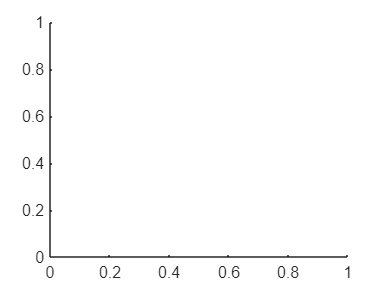

clear all
clc
hold on

%Definición parámetros en este caso KC200GT
Voc=33.10;
Isc=8.1762;
Imp=7.5699;
Vmp=27.0462;
Ns=54;
kI=0;
kv=0;
G=1000;
T=25;
%Lectura curva del módulo
Ve= transpose(xlsread('KC200GT.xlsx','a4:a39'));
Ie= transpose(xlsread('KC200GT.xlsx','b4:b39'));
%constantes físicas
q=1.60218*10^(-19);
K=1.380649*10^(-23);
%Cálculo Vth 
Vth=Ns*K*(T+273.15)/q;
m=2;
%iniciar valores posibles de n
n=1:0.001:2;
err=0.0001;
RMSE=10;
%Bucle para hallar las disitntas combinaciones de parámetros, dependiendo
%del valor de n
for i=1:length(n)
err1=10;
Rsh=m*Vmp/(Isc-Imp);
Rs1=0;
Rs2=(Voc-Vmp)/Imp;
iter=0;
while(err1>err)
    iter=iter+1;
    Rs=(Rs1+Rs2)/2;
    f=@(R) Imp+(Isc*(Rsh+R)-Voc)/Rsh*exp((Vmp+R*Imp-Voc)/(n(i)*Vth))+(Vmp+Imp*R-Isc*(R+Rsh))/Rsh;
    if f(Rs1)*f(Rs)<=0
         Rs2=Rs;
    else
         Rs1=Rs;
    end
err1=abs(Rs1-Rs2);
Rsh=(Vmp-Imp*Rs)*(Vmp-Rs*(Isc-Imp)-n(i)*Vth)/((Vmp-Imp*Rs)*(Isc-Imp)-n(i)*Vth*Imp);
end
Io=(Isc*(Rs+Rsh)-Voc)/(Rsh*exp(Voc/(n(i)*Vth)));
Iph=Io*(exp(Voc/(n(i)*Vth))-1)+Voc/Rsh;
Rsh0(i)=Rsh;
Rs0(i)=Rs;
Iph0(i)=Iph;
Io0(i)=Io;
iter0(i)=iter;
end
%Cálculo RMSE para cada valor de n
for i=1:length(n)
    %para evitar soluciones que no tengan sentido se emplea el siguiente if
    if(Rsh0(i)<0)
break
    end
    for k=1:length(Ve)
    clear I    
    syms I
    eqn1=I==Iph0(i)-Io0(i)*(exp((Ve(k)+I*Rs0(i))/(n(i)*Vth))-1)-(Ve(k)+I*Rs0(i))/Rsh0(i);
    Ik=vpasolve(eqn1,I);
    Isol(k)=double(Ik);
    end
RMSE(i)=rmse(Isol,Ie);
end
%Bucle para buscar el grupo de parámetros que tengan menor RMSE
for i=1:length(RMSE)
    if RMSE(i)==min(RMSE)
%mostrar y guardar valores en el workspace
Rs3=Rs0(i)
Rsh3=Rsh0(i)
Iph3=Iph0(i)
n3=n(i)
Io3=Io0(i)
iter=iter0(i)
%RMSE en tanto por ciento de Isc
RMSE=RMSE(i)/Isc*100
break
    end
end

Rs3 =    2.5548e-01


Rsh3 =    1.3560e+02


Iph3 =    8.1916e+00


n3 =      1


Io3 =    3.4593e-10


iter =     13


RMSE =    3.7535e-01
